6.5   （性能）实时脚本

由张志涌编写、修改于 2023.1。

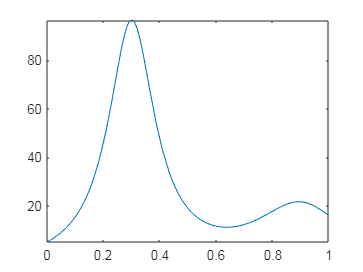

fplot(@humps,[0,1])

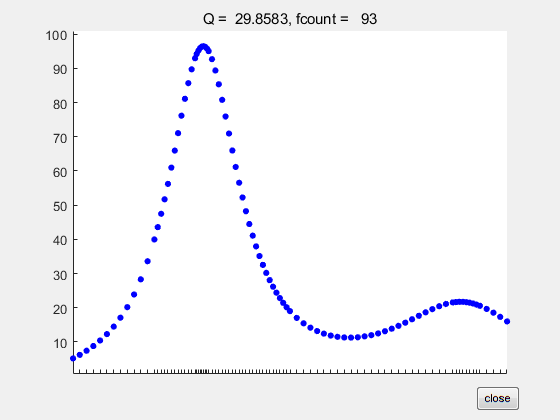

quadgui

%quadgui(@humps,0,1,1.e-4)  %该调用格式与上等价


syms x
h = 1/((x-.3)^2+.01) + 1/((x-.9)^2+.04) - 6

$$h = \frac{1}{{\left(x-\frac{9}{10}\right)}^{2}+\frac{1}{25}}+\frac{1}{{\left(x-\frac{3}{10}\right)}^{2}+\frac{1}{100}}-6$$

I = int(h)

$$I = 10\,\mathrm{atan}\left(10\,x-3\right)-6\,x+5\,\mathrm{atan}\left(5\,x-\frac{9}{2}\right)$$

D = int(h,0,1)

$$D = 11\,\pi +\mathrm{atan}\left(\frac{3588784}{993187}\right)-6$$

format long
Qexact = double(D)

Qexact =   29.858325395498674


fprintf('%7s %15s %15s %8s %13s\r\n','tol','Q',...
'fcount','err','err/tol')

    tol               Q          fcount      err       err/tol


for k = 1:12
tol = 10^(-k);
[Q,fcount] = quadtx(@humps,0,1,tol);
err = Q - Qexact;
ratio = err/tol;
fprintf('%8.0e %21.14f %7d %13.3e %9.3f\n', ...
tol,Q,fcount,err,ratio)
end

   1e-01     29.83328444174863      25    -2.504e-02    -0.250
   1e-02     29.85791444629948      41    -4.109e-04    -0.041
   1e-03     29.85834299237636      69     1.760e-05     0.018
   1e-04     29.85832444437543      93    -9.511e-07    -0.010
   1e-05     29.85832551548643     149     1.200e-07     0.012
   1e-06     29.85832540194041     265     6.442e-09     0.006
   1e-07     29.85832539499819     369    -5.005e-10    -0.005
   1e-08     29.85832539552631     605     2.763e-11     0.003
   1e-09     29.85832539549603    1061    -2.640e-12    -0.003
   1e-10     29.85832539549890    1469     2.274e-13     0.002
   1e-11     29.85832539549867    2429    -7.105e-15    -0.001
   1e-12     29.85832539549867    4245     0.000e+00     0.000
